Function

format longG

%f=@(x) (1 - exp(-x))

f = function_handle with value:
    @(x)(1-exp(-x))


%xx = linspace(0,4)

xx =                          0        0.0404040404040404        0.0808080808080808         0.121212121212121         0.161616161616162         0.202020202020202         0.242424242424242         0.282828282828283         0.323232323232323         0.363636363636364         0.404040404040404         0.444444444444444         0.484848484848485         0.525252525252525         0.565656565656566         0.606060606060606         0.646464646464647         0.686868686868687         0.727272727272727         0.767676767676768         0.808080808080808         0.848484848484849         0.888888888888889         0.929292929292929          0.96969696969697          1.01010101010101          1.05050505050505          1.09090909090909          1.13131313131313          1.17171717171717          1.21212121212121          1.25252525252525          1.29292929292929          1.33333333333333          1.37373737373737          1.41414141414141          1.45454545454545           1.4949494949495       

%yy = f(xx)

yy =                          0        0.0395986801876422        0.0776293049026812         0.114153967072293         0.149232300825689         0.182921578859269         0.215276805946244         0.246350808743404         0.276194322041649         0.304856071601121          0.33238285370617         0.358819611570045         0.384209508714071         0.408593999441094         0.432012896518279         0.454504436179757         0.476105340555252         0.496850877626618         0.516774918810175         0.535909994258858         0.554287345974482         0.571936978816824         0.588887709492813         0.605167213605816         0.620802070841835         0.635817808366385         0.650238942502919         0.664089018760838         0.677390650278444         0.690165554743611         0.702434589852435         0.714217787363773         0.725534385805271         0.736402861884273         0.746840960654896         0.756865724490533         0.766493520909087          0.77574006929635       

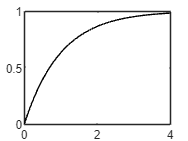

%plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0

a =      0


b = 4

b =      4


p =[2 0 -4 0 -1 1]

p =      2     0    -4     0    -1     1


q = polyint(p)

q =          0.333333333333333                         0                        -1                         0                      -0.5                         1                         0


%Itrue = diff(polyval(q,[a,b]))
Itrue = 3.018316

Itrue =                   3.018316


Plot original function along with simpson 1/3 rule with ns = 1

ns = 1

ns =      1


x = linspace(a,b,2*ns+1)

x =      0     2     4


y = f(x)

y =                          0         0.864664716763387         0.981684361111266



p2 = polyfit(x,y,2)

p2 =        -0.0934556340519386         0.619243626485571       5.8885969042226e-17


yy2 = polyval(p2,xx)

yy2 =        5.8885969042226e-17        0.0248673794453072        0.0494296287722935        0.0736867479809591        0.0976387370713038         0.121285596043328         0.144627324897031         0.167663923632413         0.190395392249475         0.212821730748216         0.234942939128636         0.256759017390735         0.278269965534514         0.299475783559971         0.320376471467108         0.340972029255924          0.36126245692642         0.381247754478594         0.400927921912448         0.420302959227981         0.439372866425193         0.458137643504084         0.476597290464655         0.494751807306905         0.512601194030834         0.530145450636442         0.547384577123729         0.564318573492696         0.580947439743342         0.597271175875667         0.613289781889671         0.629003257785355         0.644411603562717         0.659514819221759         0.674312904762481         0.688805860184881          0.70299368548896         0.716876380674719      

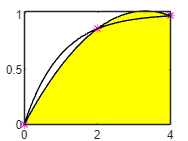

figure
area(xx,yy2,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(x,y,'m*')
plot(xx,yy,'k-')

h = (b-a)/3; % 3/8
%h = (b-a)/2; % 1/3
%Iap1peach = sim13(f,a,b,4*2)%don't forget *2
%Iap1phoo = (h/3)*(f(a)+4*f((a+b)/2)+f(b)) %1/3
Iap1phoo = (3*h/8)*(f(a)+3*f((2*a+b)/3)+3*f((a+2*b)/3)+f(b)) % 3/8 

Iap1phoo =           2.99122129654784


err = abs(Itrue - Iap1phoo)/Itrue

err =        0.00897676169498475


err = err*100

err =          0.897676169498475


Plot original function along with simpson 1/3 rule with ns = 2

ns = 2

ns =      2


x = linspace(a,b,2*ns+1)

x =      0     1     2     3     4


y = f(x)

y =                          0         0.632120558828558         0.864664716763387         0.950212931632136         0.981684361111266



figure
color = ['g','y']

color = 'gy'

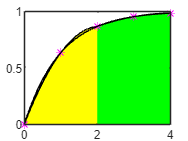

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule with ns = 3

ns = 3

ns =      3


x = linspace(a,b,2*ns+1)

x =                          0         0.666666666666667          1.33333333333333                         2          2.66666666666667          3.33333333333333                         4


y = f(x)

y =                          0         0.486582880967408         0.736402861884273         0.864664716763387         0.930516548777198         0.964326006652748         0.981684361111266



figure
color = ['g','y']

color = 'gy'

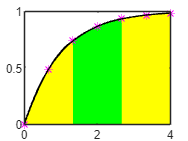

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')

Plot original function along with simpson 1/3 rule from ns = 1 to 10